## Rendering noise analysis

We use this script to calculate how graphics rendering noise depends on the the rendering parameters, such as the number of rays  cast from each pixel. The rendering noise also can vary with the number of bounces, the ray sampler algorithm and local properties of the scene.

The idea of this script is to compare the amount of noise we obtain when we render the image using an **ideal sensor. **Were there no rendering noise, the ideal sensor noise would be entirely photon noise (also called shot noise).  The shot noise has a Poisson distribution: for the large number of photons this is approximately Normal with a mean equal to the variance.  This script makes a series of plots that compares the **actual sensor noise in the rendered image** with the sensor noise expected for **a perfect rendering** (mean equals variance).  

In practice, when doing simulations, we try to select rendering parameters that bring the sensor noise close to the photon noise.

This script includes two main examples;  it is possible to create many different cases and we will be creating more in the future. But this script is already useful to us and it explains the principles.

- The first case illustrates the analysis using a flat surface directly facing the camera.  This is a very simple case because there are no inter-reflections and we can select a small portion of the sensor image with very little or no relative illumination falloff.  We illustrate the case using two different optics: a pinhole  and a typical Double Gauss lens.  The point of this comparison is to show that we do well with relatively few rays when using a pinhole.  As we introduce the lens and need to sample the lens aperture, we must substantially increase the number of rays to approach the Poisson noise limit.

- The second case illustrates the analysis using a Cornell Box.  This is a much more complicated scene which include inter-reflections and a strong **relative illumination**. It is not easy to find a region in this image where the illumination is perfectly constant. Note:  If the scene radiance is not completely constant across the measured sensor region, the variance will be **larger** than the ideal photon noise case.  For this script we selected a small region on the back wall and compared the photon noise there with the ideal expectation.  As you will see, the rendering gets close to the ideal but never quite reaches it.  This is likely because no region is perfectly uniform.

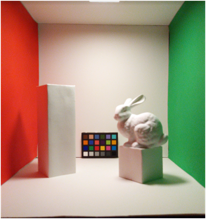

## Initialize ISETCam and ISET3d

%% Initialize and check that Docker is configured
ieInit;
if ~piDockerExists, piDockerConfig; end

## Flat surface: pinhole

We analyze the rendering noise using a flat surface and an ideal monochrome sensor with no electronic noise.  

The case of a pinhole camera runs relatively quickly.  This case converges quickly because there is almost no aperture sampling.

rays = [4 64 128 512];
[rn, pn] = piRenderNoise('rays',rays, 'lensname','pinhole');

Read 1 materials.
Read 1 textures.
***Scene parsed.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface":"/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/renderings/flatSurface.dat /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
*** Rendering time for flatSurface:  0.9 sec ***

  Reading image h=64 x w=64 x 31 spectral planes.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" --volume="/Us

Plot the results

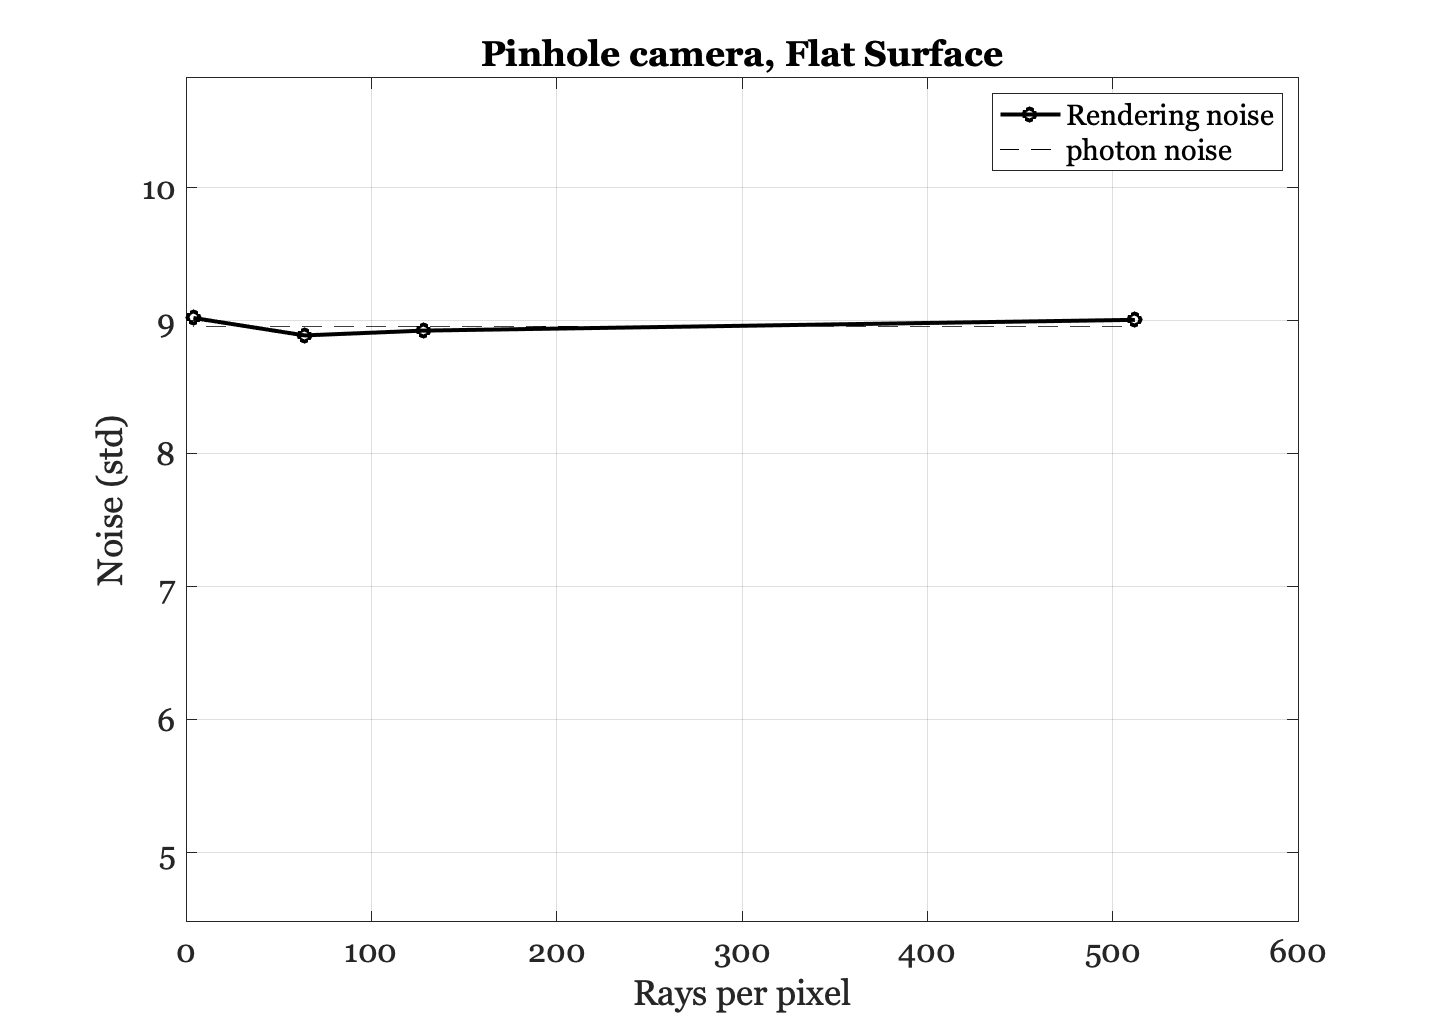

ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
legend('Rendering noise','photon noise');
title('Pinhole camera, Flat Surface')
grid on; xlabel('Rays per pixel'); ylabel('Noise (std)');
ylim([pn/2 max(rn)*1.2]);

For this scene that contains only a flat surface, and a pinhole camera, the rendering noise is  very close to the photon noise level with very few rays.

## Flat surface:  lens

Now we introduce a double-Gauss lens into the camera.  The total noise level converges slowly to the photon noise level alone.

rays = [64 128 512 1024];
[rn, pn] = piRenderNoise('rays',rays,'lensname','dgauss.22deg.12.5mm.json');

Read 1 materials.
Read 1 textures.
***Scene parsed.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface":"/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/renderings/flatSurface.dat /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
*** Rendering time for flatSurface:  10.0 sec ***

  Reading image h=64 x w=64 x 31 spectral planes.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" --volume="/U

Plot the curve

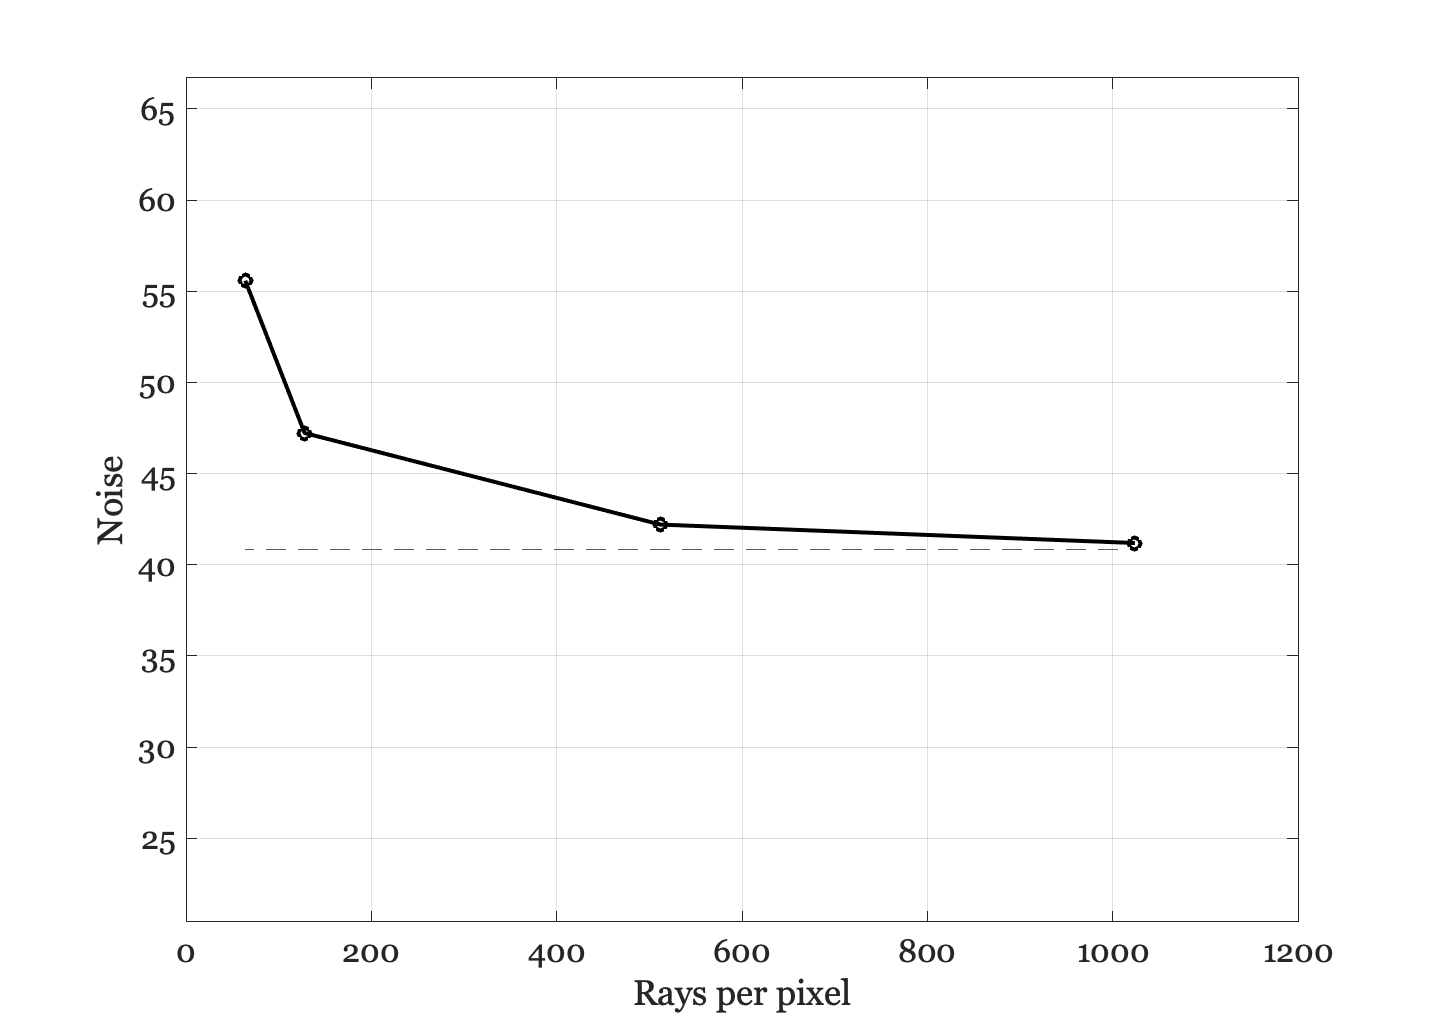

ieNewGraphWin;
plot(rays,rn,'-ok','Linewidth',2);
line([rays(1), rays(end)],[pn, pn],'Color','k','Linestyle','--');
grid on; xlabel('Rays per pixel'); ylabel('Noise'); ylim([pn/2 max(rn)*1.2]);

In this case are very close at 512 and get there at 1024.

## Cornell box:  back surface

When rendering more complex scenes, it is important to find locally uniform regions where we can estimate the number of photons without illuminant or surface nonuniformities.  Also, for complex scenes the number of bounces may be relevant because of inter-reflections. We illustrate the calculation using a Cornell box which does have significant inter-reflections.  

We start with the back surface in the middle.  There are are probably not as many inter-reflections at that location. We can try other parts of the scene in the future.

By making a very small film diagonal, we only measure a small part of the image.  Even though it is small, there is probably still some shading that increases the render noise value.

This section takes a while to run (5 minutes on an old Mac).  

rays = [64 512 1024];
nBounceList = [1 2 4 8];
rnList = zeros(numel(nBounceList), numel(rays));
pnList = zeros(1, numel(nBounceList));

for ii=1:numel(nBounceList)
    [rn, pn, idealSensor] = piRenderNoise('rays',rays,...
        'scene name','cornell box reference', ...
        'film diagonal',0.15, ...
        'nbounces',nBounceList(ii));
    rnList(ii, :) = rn;
    pnList(ii) = pn;
end

Read 1 materials.
Read 1 textures.
***Scene parsed.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference":"/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  10.4 sec ***

  Reading image h=64 x w=64 x 31 spectral planes.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docke

### Render the Cornell box 

[~,~,~,~,oi] = piRenderNoise('rays',64,...
    'scene name','cornell box reference', ...
    'film diagonal',15, ...
    'nbounces',1);

Read 1 materials.
Read 1 textures.
***Scene parsed.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference":"/Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  7.5 sec ***

  Reading image h=64 x w=64 x 31 spectral planes.
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker

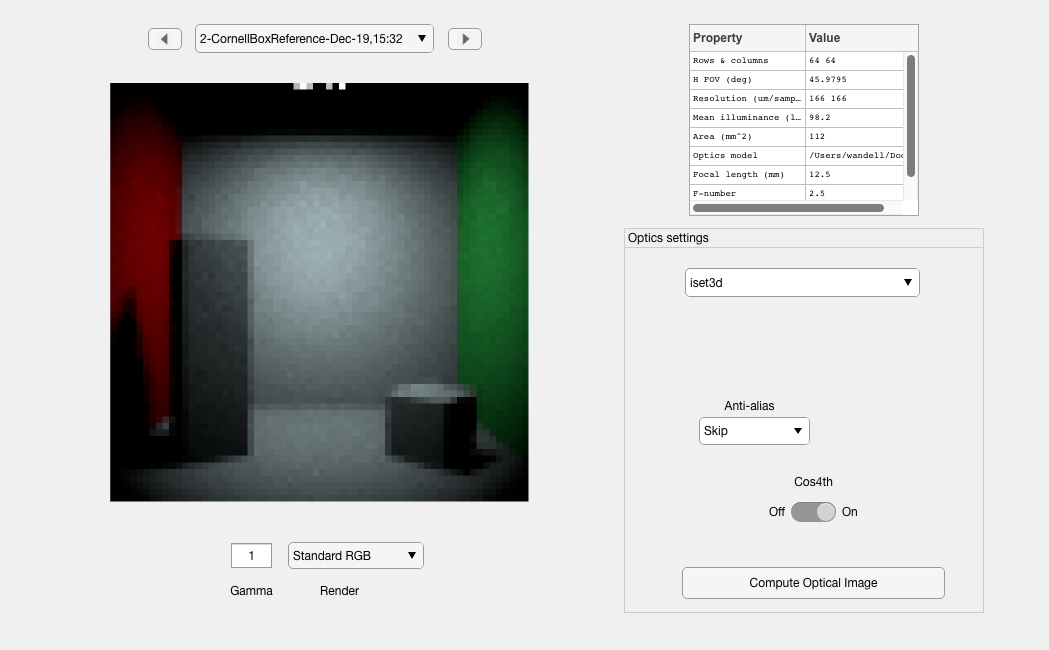

oiWindow(oi);

### Now the noise vs. nRays curves, parameterized by bounces

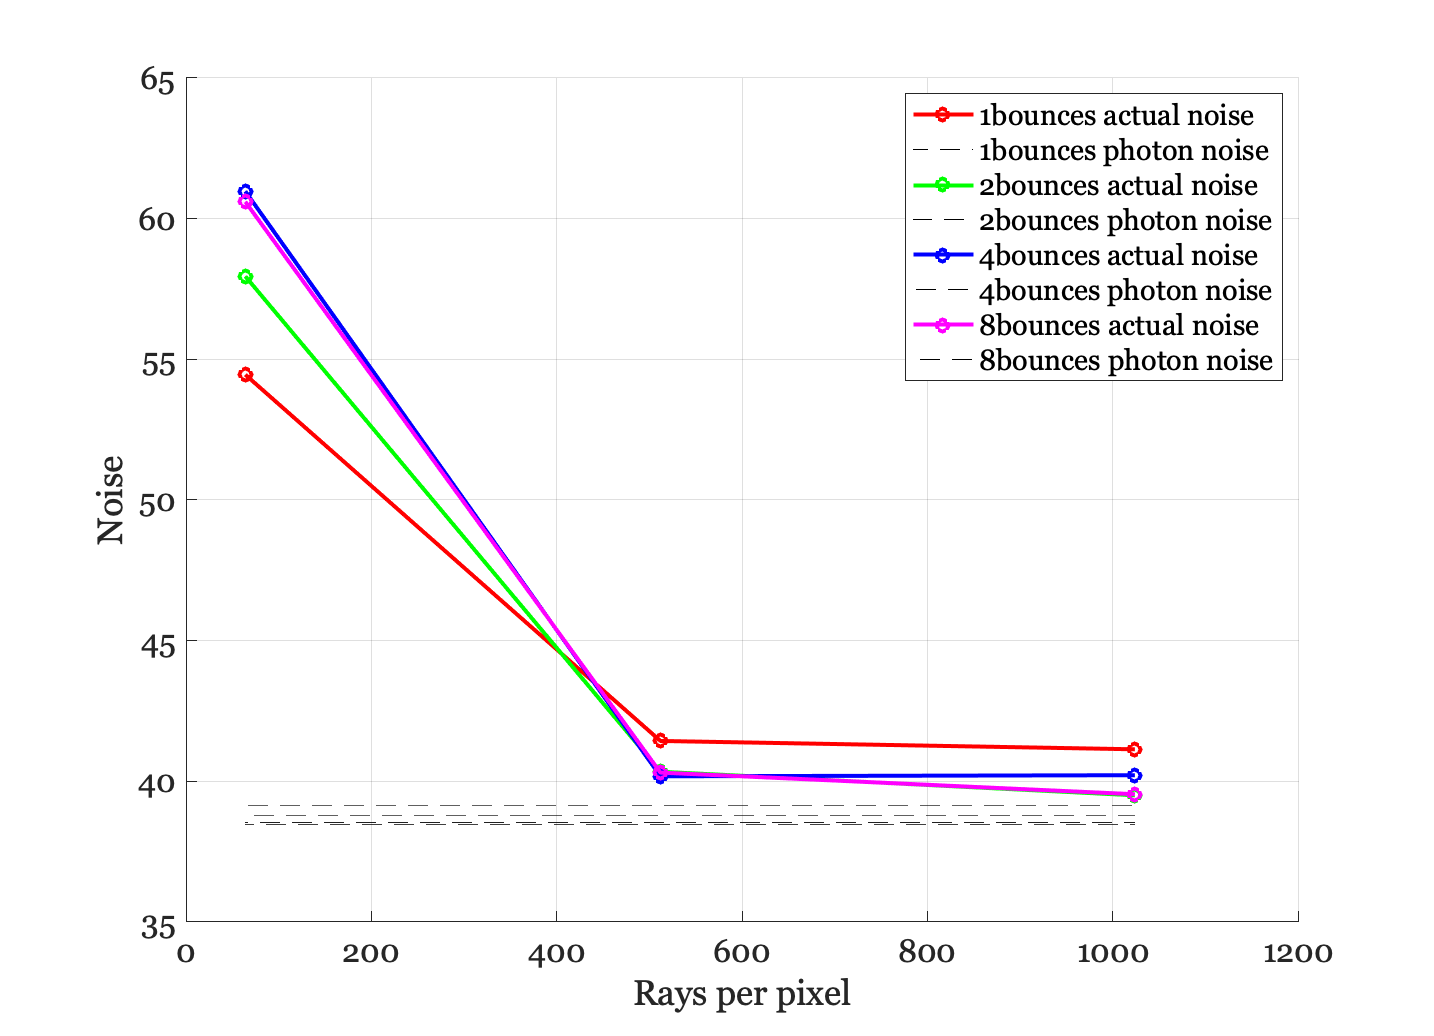

ieNewGraphWin;
legendName = cell(1, 2 * numel(nBounceList));
hold all
for ii=1:numel(nBounceList)
    plot(rays, rnList(ii,:), '-o','Linewidth',2);
    line([rays(1), rays(end)],[pnList(ii), pnList(ii)],'Linestyle','--','Color','k');
    legendName{2*(ii-1)+1} = [num2str(nBounceList(ii)), 'bounces actual noise'];
    legendName{2*ii} = [num2str(nBounceList(ii)), 'bounces photon noise'];
end
grid on; xlabel('Rays per pixel'); ylabel('Noise');
legend(legendName);